Nb = 5;
N = 64;
F_s = 2000;
T_s = 1/F_s;
A1 = 1.05;
A2 = 2.1;
f1 = 250;
f2 = 750;   
disp("fe")

fe


## 1

disp("ЗАДАНИЕ НОМЕР 1")
n = 0:N-1;
w1 = 2*pi*f1/F_s;
w2 = 2*pi*f2/F_s;
x = A1*cos(w1*n + pi/4) + A2*cos(w2*n + pi/16)

x =     2.8021   -1.7461   -0.3328    0.1167   -2.8021    1.7461    0.3328   -0.1167    2.8021   -1.7461   -0.3328    0.1167   -2.8021    1.7461    0.3328   -0.1167    2.8021   -1.7461   -0.3328    0.1167   -2.8021    1.7461    0.3328   -0.1167    2.8021   -1.7461   -0.3328    0.1167   -2.8021    1.7461    0.3328   -0.1167    2.8021   -1.7461   -0.3328    0.1167   -2.8021    1.7461    0.3328   -0.1167    2.8021   -1.7461   -0.3328    0.1167   -2.8021    1.7461    0.3328   -0.1167    2.8021   -1.7461


X = fft(x);
MOD_X = (2/N )*abs(X);
MOD_X(1) = (1/N)*abs(X(1))

MOD_X =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0500    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.1000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.1000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


PHASE_X = angle(X);
disp("АС и ФС")

АС и ФС


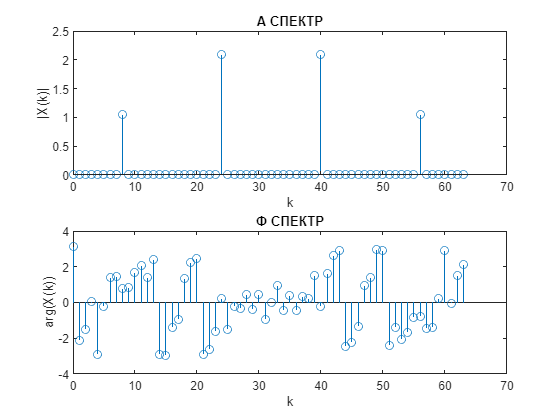

figure;
subplot(2,1,1);
stem(n, MOD_X), title("А СПЕКТР"), ylabel("|X(k)|"), xlabel("k"), ylim([0, 2.5]);
subplot(2,1,2);
stem(n, PHASE_X), title("Ф СПЕКТР"), ylabel("arg(X(k))"), xlabel("k");

disp("результат после ПЕРВОГО критерия")

результат после ПЕРВОГО критерия


e1 = 0.1

e1 = 0.1000

[MODm_1,m_1] = fft_e1(MOD_X,e1) ;
for i = 1:length(m_1)
fprintf("Амлитутда: %.f номер гармоники: %.f \n", MODm_1(i), m_1(i))
end

Амлитутда: 1 номер гармоники: 8 
Амлитутда: 2 номер гармоники: 24 
Амлитутда: 2 номер гармоники: 40 
Амлитутда: 1 номер гармоники: 56 


## 2

disp("ЗАДАНИЕ НОМЕР 2")

ЗАДАНИЕ НОМЕР 2


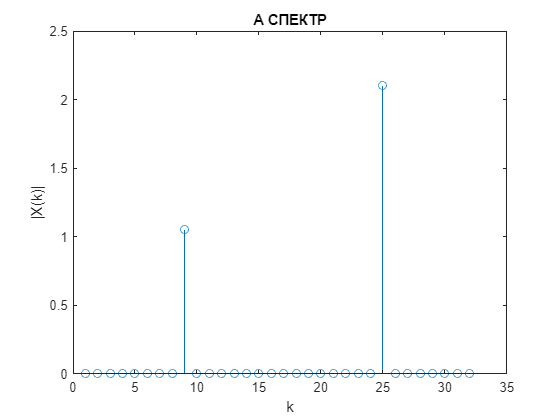

new_X = X(1:N/2);
MOD_X_2 = (2/N)*abs(new_X);
MOD_X_2(1) = (1/N)*abs(new_X(1));
PHASE_X_2 = angle(new_X);
stem(1:N/2, MOD_X_2), title("А СПЕКТР"), ylabel("|X(k)|"), xlabel("k"), ylim([0, 2.5]);

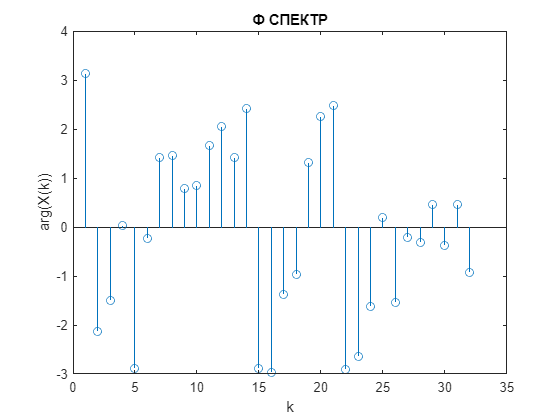

stem(1:N/2, PHASE_X_2), title("Ф СПЕКТР"), ylabel("arg(X(k))"), xlabel("k");

## 3

disp("ЗАДАНИЕ НОМЕР 3")

ЗАДАНИЕ НОМЕР 3


x2 = A1*cos(w1*n)

x2 =     1.0500    0.7425    0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425    0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425    0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425   -0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425   -0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425   -0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425


x3 = A2*sin(w2*n)

x3 =          0    1.4849   -2.1000    1.4849    0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849   -2.1000    1.4849    0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849   -2.1000    1.4849    0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849   -2.1000    1.4849   -0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849   -2.1000    1.4849    0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849   -2.1000    1.4849    0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849


x0 = [x2(1:N/2) x3((N+2)/2:N)]

x0 =     1.0500    0.7425    0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425    0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425    0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425    1.0500    0.7425   -0.0000   -0.7425   -1.0500   -0.7425   -0.0000    0.7425   -0.0000    1.4849   -2.1000    1.4849    0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849   -2.1000    1.4849    0.0000   -1.4849    2.1000   -1.4849   -0.0000    1.4849


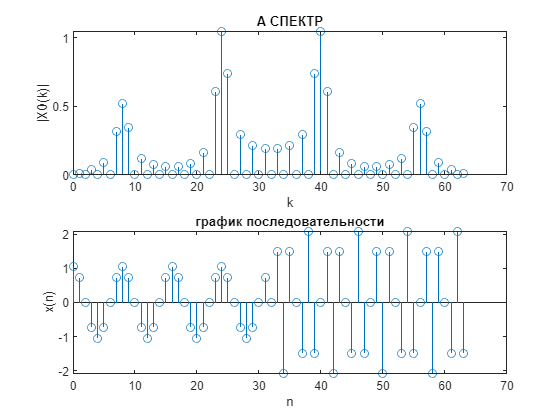

stem(n, x0), title("график последовательности"), ylabel("x(n)"), xlabel("n");

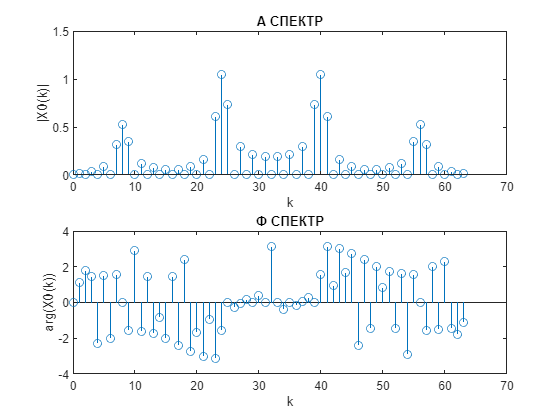

X0 = fft(x0);
MOD_X0 = (2/N)*abs(X0);
MOD_X0(1) = (1/N)*abs(X0(1));
PHASE_X0 = angle(X0);
figure;
subplot(2,1,1);
stem(n, MOD_X0), title("А СПЕКТР"), ylabel("|X0(k)|"), xlabel("k"), ylim([0 1.5]);
subplot(2,1,2);
stem(n, PHASE_X0), title("Ф СПЕКТР"), ylabel("arg(X0(k))"), xlabel("k");

## 4

disp("ЗАДАНИЕ НОМЕР 4")

ЗАДАНИЕ НОМЕР 4


x_del = [1 zeros(1, N-2)]

x_del =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


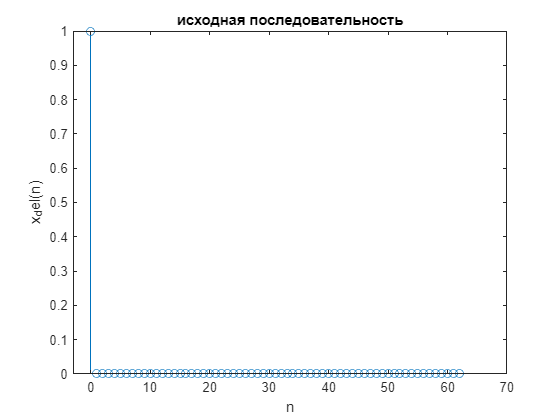

X_del = fft(x_del);
MOD_X_del = (2/N)*abs(X_del);
MOD_X_del(1) = (1/N)*abs(X_del(1));
figure;
stem(0:length(x_del)-1, x_del), title("исходная последовательность"), ylabel("x_del(n)"), xlabel("n"), xlim([-3 70]);

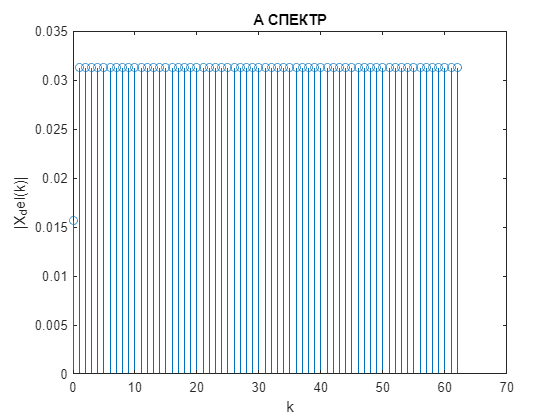

stem(0:length(x_del)-1, MOD_X_del), title("А СПЕКТР"), ylabel("|X_del(k)|"), xlabel("k");

## 5

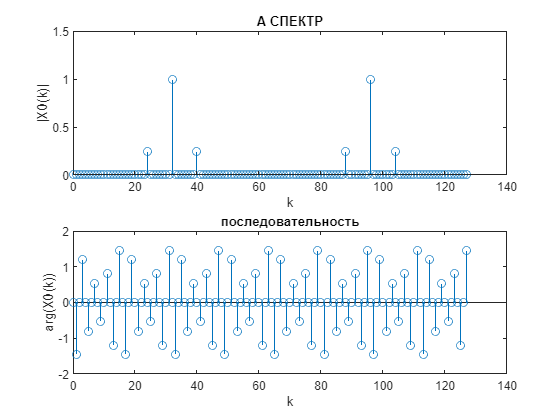

disp("ЗАДАНИЕ НОМЕР 5")
C = 1;
Omega = pi/8;
Fi = 0;
w = pi/2;
fi = pi/2;
m = 0.5;
n_2 = 0:2*N-1;
x4 = C*(1+m*cos(Omega*n_2+Fi)).*cos(w*n_2+fi);

X4 = fft(x4);
MOD_X4 = (1/N)*abs(X4);
MOD_X4(1) = (1/2*N)*abs(X4(1));

figure;
subplot(2,1,1);
stem(n_2, MOD_X4), title("А СПЕКТР"), ylabel("|X0(k)|"), xlabel("k"), ylim([0 1.5]);
subplot(2,1,2);
stem(n_2, x4), title("последовательность"), ylabel("arg(X0(k))"), xlabel("k");

## 6

disp("ЗАДАНИЕ НОМЕР 6")

ЗАДАНИЕ НОМЕР 6


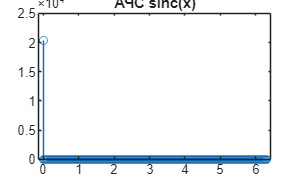

F_s_6 = 2000;
t_6 = -500*(N-1)*(1/F_s_6):1/F_s_6:500*(N-1)*(1/F_s_6);
x_6 = sinc(pi*t_6);
X6 = fft(x_6);
MOD_X6 = (2/length(t_6))*abs(X6);
MOD_X6(1) = (1/length(t_6))*abs(X6(1));
figure;
stem(0:(length(t_6)-1), MOD_X4), title('АЧС sinc(x)');

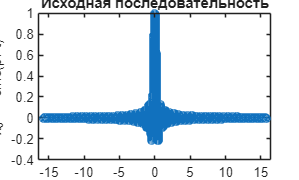

stem(t_6, x_6), title('Исходная последовательность'), xlabel('t,c'), ylabel('x_6 = sinc(pi*t)');

## 7

disp("ЗАДАНИЕ НОМЕР 7")

ЗАДАНИЕ НОМЕР 7


a = 0.0005;
w1_7 = pi/12;
n_7 = -3*(N-1):1:3*(N-1)

n_7 =   -189  -188  -187  -186  -185  -184  -183  -182  -181  -180  -179  -178  -177  -176  -175  -174  -173  -172  -171  -170  -169  -168  -167  -166  -165  -164  -163  -162  -161  -160  -159  -158  -157  -156  -155  -154  -153  -152  -151  -150  -149  -148  -147  -146  -145  -144  -143  -142  -141  -140


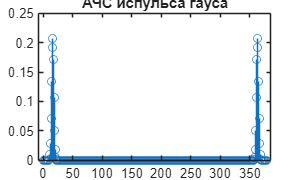

x_n_7 = exp(-a*(n.*n)).*cos(w1_7*n);
X7 = fft(x_n_7);
MOD_X7 = (2/length(n_7))*abs(X7);
MOD_X7(1) = (1/length(n_7))*abs(X7(1));
figure;
stem(0:(length(n_7)-1), MOD_X7), title('АЧС испульса гауса');

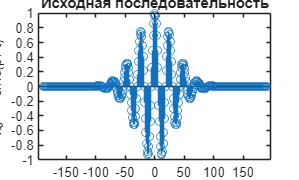

stem(n_7, x_n_7), title('Исходная последовательность'), xlabel('t,c'), ylabel('x_6 = sinc(pi*t)');

function [MODm,m] = fft_e1(MODX,e1) 
% Определение значений модуля ДПФ и частот полезного сигнала 
% 
% MODX — вектор значений модуля ДПФ смеси сигнала с шумом 
% e1 — заданный порог 
% 
% MODm — вектор значений модуля ДПФ полезного сигнала 
% m — вектор значений частот полезного сигнала 
% 
i = 1; 
MAX = max(MODX); 
for k = 1:length(MODX) 
    if (MODX(k)/MAX)>e1 
        MODm(i) = MODX(k); 
        m(i) = k-1; 
        i = i+1; 
    end 
end
end